Open the model.

%Parametrs
Ki = 1e-1;%Kof Integrator
Kr = 10;%Reward Kof
Kd = -800;%isdone Kof
Ks = 10;%signal Kof
%Traning options

MaxEp = 1500; %max epochs
ValueStop = 0; %the stop value

%Model
mdl = 'csdesigner';
open_system(mdl)
nObs=8;%number of observations
nAct=2;%number of actions
action = 0.1;%parametr actInfo

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;

Assign the agent block path information, and create `rlNumericSpec` and `rlFiniteSetSpec` objects for the observation and action information. You can use dot notation to assign property values of the `rlNumericSpec` and `rlFiniteSetSpec` objects.

agentBlk = [mdl '/RL Agent'];
obsInfo = rlNumericSpec([nObs 1])

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [4 1]
       DataType: "double"


%actInfo = rlNumericSpec([nAct 1])%,'LowerLimit',-10*ones(2,1),...
                              %'UpperLimit',10*ones(2,1))
                          
actInfo = rlFiniteSetSpec({[-action; -action], [0 ;-action], [action; -action], ...
                            [-action; 0], [0; 0], [action ;0], ...
                            [action ;action], [0; action], [action; action]})

actInfo =   rlFiniteSetSpec with properties:

       Elements: {9×1 cell}
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [2 1]
       DataType: "double"


% %actInfo = rlFiniteSetSpec({[-0.1; -0.1], [0 ;-0.1], [0.1; -0.1], ...
%                             [-0.1; 0], [0; 0], [0.1 ;0], ...
%                             [0.1 ;0.1], [0; 0.1], [0.1; 0.1]})
%actInfo = rlFiniteSetSpec([-1 0 -1])                        
obsInfo.Name = 'observations';
actInfo.Name = 'voltage';


Create the reinforcement learning environment for the Simulink model using information extracted in the previous steps.

env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo)

env =   SimulinkEnvWithAgent with properties:

             Model: "csdesigner"
        AgentBlock: "csdesigner/RL Agent"
          ResetFcn: []
    UseFastRestart: 'on'



% % load predefined environment
% env = rlPredefinedEnv("CartPole-Discrete");
% 
% % get observation and specification info
% obsInfo = getObservationInfo(env);
% actInfo = getActionInfo(env);

You can also include a reset function using dot notation. For this example, consider randomly initializing `theta0` in the model workspace.

%env.ResetFcn = @(in) setVariable(in,'theta0',randn,'Workspace',mdl)

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds

Tss = 0.01;
Tf = 3;

## Create DQN agent

A DQN agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the state and action, and two outputs. The input size of the state path is `[2 1 1]` since the environment provides 2 observations. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    imageInputLayer([nObs 1 1],'Normalization','none','Name','state')
    fullyConnectedLayer(24,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(28,'Name','CriticStateFC2')]

statePath =   4x1 Layer array with layers:

     1   'state'            Image Input       4x1x1 images
     2   'CriticStateFC1'   Fully Connected   24 fully connected layer
     3   'CriticRelu1'      ReLU              ReLU
     4   'CriticStateFC2'   Fully Connected   28 fully connected layer

actionPath = [
    imageInputLayer([nAct 1 1],'Normalization','none','Name','action')
    fullyConnectedLayer(28,'Name','CriticActionFC1','BiasLearnRateFactor',0)]

actionPath =   2x1 Layer array with layers:

     1   'action'            Image Input       2x1x1 images
     2   'CriticActionFC1'   Fully Connected   28 fully connected layer

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','output')]

commonPath =   3x1 Layer array with layers:

     1   'add'                Addition          Element-wise addition of 2 inputs
     2   'CriticCommonRelu'   ReLU              ReLU
     3   'output'             Fully Connected   1 fully connected layer

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

View the critic network configuration.

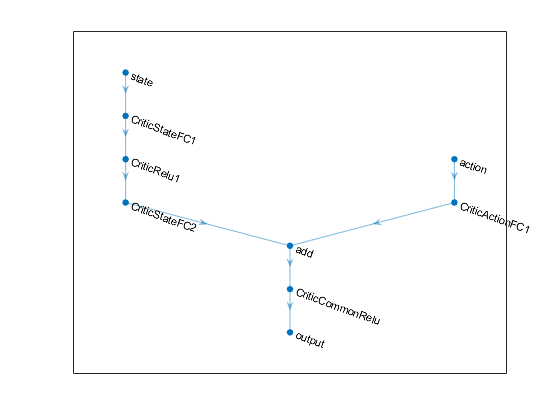

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOptions = rlRepresentationOptions('LearnRate',0.01,'Optimizer',"sgdm");%,'GradientThreshold',0.1);
criticOptions.OptimizerParameters.Momentum = 0.8;


Create the critic representation using the specified deep neural network and options. You must also specify the action and observation info for the critic, which you obtain from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "observations"
    Description: [0×0 string]
      Dimension: [4 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlFiniteSetSpec with properties:

       Elements: {9×1 cell}
           Name: "voltage"
    Description: [0×0 string]
      Dimension: [2 1]
       DataType: "double"


critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,...
    'Observation',{'state'},'Action',{'action'},criticOptions)

critic =   rlQValueRepresentation with properties:

         ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
    ObservationInfo: [1×1 rl.util.rlNumericSpec]
            Options: [1×1 rl.option.rlRepresentationOptions]


To create the DQN agent, first specify the DQN agent options using [`rlDQNAgentOptions`](docid:rl_ref#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e).

agentOptions = rlDQNAgentOptions(...
    'SampleTime',Tss,...
    'TargetSmoothFactor',1e-3,...
    'SaveExperienceBufferWithAgent',1,...
    'ExperienceBufferLength',3000,... 
    'UseDoubleDQN',false,...
    'DiscountFactor',0.7,...
    'MiniBatchSize',50);

Then, create the DQN agent using the specified critic representation and agent options. For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

agent = rlDQNAgent(critic,agentOptions)

agent =   rlDQNAgent with properties:

        AgentOptions: [1×1 rl.option.rlDQNAgentOptions]
    ExperienceBuffer: [1×1 rl.util.ExperienceBuffer]


## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most `1000` episodes, with each episode lasting at most `500` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than `-1100` over five consecutive episodes. At this point, the agent can quickly balance the pendulum in the upright position using minimal control effort.

- Save a copy of the agent for each episode where the cumulative reward is greater than `-1100`.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

trainingOptions = rlTrainingOptions( ...
    'MaxEpisodes',MaxEp,...
    'MaxStepsPerEpisode',(Tf/Tss),...
    'ScoreAveragingWindowLength',5,...
    'Verbose',false,...
    'Plots','training-progress', ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',ValueStop,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',ValueStop);


if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainingOptions);
    
    curDir = pwd;
saveDir = 'savedAgents';
cd(saveDir)
save(['trainedAgent_2D_' datestr(now,'mm_DD_YYYY_HHMM')],'agent','trainingStats');
cd(curDir)
    
else
    % Load pretrained agent for the example.
    load('SimulinkPendulumDQN.mat','agent');
end